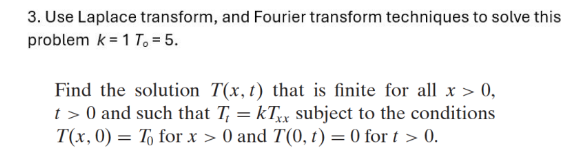

clearvars;clc;clf;
% Parameters
k = 1; 
T0 = 5; 
x = linspace(0, 10, 100);
t = linspace(0.1, 5, 100); 

% Initialize the temperature matrix
T_xt = zeros(length(x), length(t));

**solution T(x, t) using the erfc function**

for i = 1:length(t)
    T_xt(:, i) = T0 * erfc(x / (2 * sqrt(k * t(i))));
end

**Plot graph 3D**

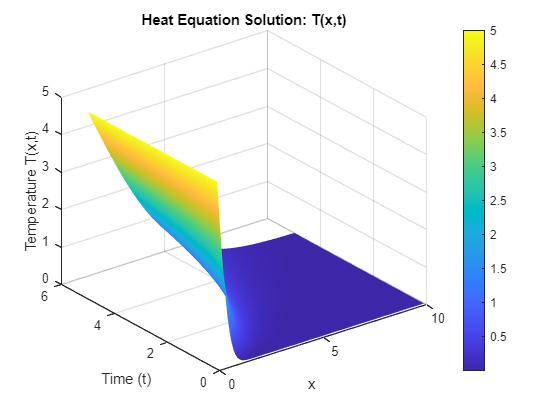

figure;
[X, T] = meshgrid(x, t);
surf(X, T, T_xt');
shading interp;
title('Heat Equation Solution: T(x,t)');
xlabel('x');
ylabel('Time (t)');
zlabel('Temperature T(x,t)');
colorbar;
grid on;

**Plot the temperature profile at different **

figure;
hold on;
time_indices = [1, 20, 40, 60, 80, 100]; 
for idx = time_indices
    plot(x, T_xt(:, idx), 'LineWidth', 1.5);
end
title('Temperature Profile T(x,t) at Different Times');
xlabel('x');
ylabel('Temperature T(x,t)');
legend(arrayfun(@(t_idx) sprintf('t=%.2f', t(t_idx)), time_indices, 'UniformOutput', false));
grid on;